## CLEAR

clc, clear all, close all

## Launch-Landing Module

% LLM Parameters
LLM.name = "Launch-Landing Module";
LLM.type = "cylinder";
LLM.color = [0.2 0.6 1]; % RGB

LLM.propellant.mass = 8607.5;
LLM.propellant.isp = 455;

LLM.mass.dry = 5000;
LLM.mass.wet_descent = LLM.mass.dry + LLM.propellant.mass;

LLM.size.height = 7;
LLM.cog = [0 0 LLM.size.height/2];
if LLM.type == "cylinder"
    LLM.size.radius = 4;
    LLM.area_inertia = inertia_cylinder(LLM.size.radius, LLM.size.height);
elseif LLM.type == "hollow_cylinder"
    LLM.size.radius_out = 3.8;
    LLM.size.radius_in = 1.8;
    LLM.area_inertia = inertia_hollow_cylinder(LLM.size.radius_in,LLM.size.radius_out,LLM.height);
end

% Thruster Main Engine
LLM.main_engine.Fmax = 222500;
LLM.main_engine.tau = 1.2;
LLM.main_engine.u_min = 0.1; % Minimum percentage for throttability
LLM.main_engine.gimbal_deg = 10; % max angle of gimbal
LLM.main_engine.gimbal_rad = pi/180*10;

% Reaction Control System
LLM.rcs.Fmax = 500;
LLM.rcs.tau = 0.1;

## Space Tug

% ST Parameters
ST.name = "Space Tug";
ST.type = "cylinder";

ST.propellant.mass = 7212;
ST.propellant.isp = LLM.propellant.isp;

ST.mass.dry = 3000;
ST.mass.wet = ST.mass.dry + ST.propellant.mass;

ST.size.radius = 2; 
ST.size.height = 8;
ST.size.offset = 4.5; % if 0, ST attach on the upper lander surface; if > 0, it will be shifted down, in the lander hole

ST.color = [1 0.5 0.2]; % RGB

ST.area_inertia = inertia_cylinder(ST.size.radius, ST.size.height);
ST.cog = [0 0 ST.size.height/2 + LLM.size.height-ST.size.offset];

## GEO Target

% GEO Sat Parameters
GEOSAT.name = "GEO Satellite";
GEOSAT.type = "box";

GEOSAT.propellant.mass = 0;

GEOSAT.mass.dry = 3000;
GEOSAT.mass.wet = GEOSAT.mass.dry + GEOSAT.propellant.mass;

GEOSAT.size.length = 2.5;
GEOSAT.size.width = 2.5;
GEOSAT.size.height = 4;
GEOSAT.color = [0.8 0.2 0.2];

% GEO Sat Inertia Matrix
GEOSAT.area_inertia = inertia_box(GEOSAT.size.height, GEOSAT.size.width, GEOSAT.size.length);

GEOSAT.cog = [0 0 GEOSAT.size.height/2 + LLM.size.height + ST.size.height - ST.size.offset];

## Multi-Body System in Landing Phase

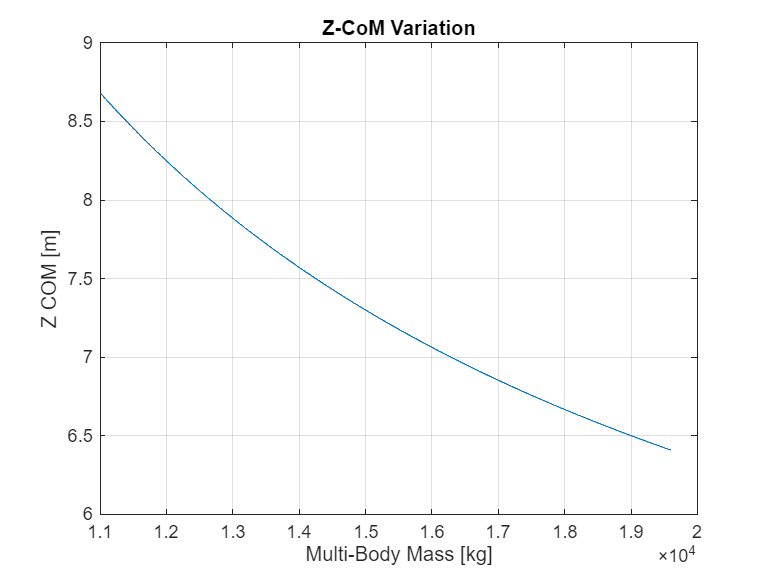

%%% Multi-Body Center of Mass
Mi = LLM.mass.wet_descent + ST.mass.dry + GEOSAT.mass.dry; % Initial mass at Landing
Mf = LLM.mass.dry + ST.mass.dry + GEOSAT.mass.dry; % Final mass after touchdown

N = 1000; % Number of points in in the plot
LLM_mass_landing = linspace(Mf,Mi,N);
COM_values = [];

for i = LLM_mass_landing
    r_com = (i*LLM.cog + ...
             ST.mass.dry*ST.cog + ...
             GEOSAT.mass.dry*GEOSAT.cog)/i;
    COM_values = [COM_values, r_com'];
end

figure
plot(LLM_mass_landing, COM_values(3,:), '-')
xlabel('Multi-Body Mass [kg]')
ylabel('Z COM [m]')
grid on
title('Z-CoM Variation')

%%% Multi-Body Total Inertia during Descent Phase

% CoM di ciascun corpo come COLONNE 3xN
centers_of_mass = [LLM.cog.' , ST.cog.' , GEOSAT.cog.'];  % 3x3, colonne = corpi

ST.mass_inertia    = ST.mass.dry    * ST.area_inertia;     % 3x3
GEOSAT.mass_inertia = GEOSAT.mass.dry * GEOSAT.area_inertia; % 3x3

Inertia_MB = zeros(3,3,numel(LLM_mass_landing));  % array 3x3xN per salvare tutte le matrici
k = 1;
for mLLM = LLM_mass_landing
    masses   = [mLLM, ST.mass.dry, GEOSAT.mass.dry];       % 1x3
    inertias = { mLLM*LLM.area_inertia , ST.mass_inertia , GEOSAT.mass_inertia }; % 1x3 cell di 3x3
    I_total  = total_inertia(masses, centers_of_mass, inertias);
    Inertia_MB(:,:,k) = I_total;
    k = k + 1;
end

% (facoltativo) verifica i fuori-diagonale nell’ultima istanza
It = Inertia_MB(:,:,end);
It = 0.5*(It+It.');  % simmetrizza
off = norm([It(1,2) It(1,3) It(2,3)]);
fprintf('||offdiag|| = %.3e\n', off);

||offdiag|| = 0.000e+00


Inertia_MB

Inertia_MB = Inertia_MB(:,:,1) =

   1.0e+05 *

    3.0481         0         0
         0    3.0724         0
         0         0    0.9956


Inertia_MB(:,:,2) =

   1.0e+05 *

    3.0491         0         0
         0    3.0735         0
         0         0    0.9963


Inertia_MB(:,:,3) =

   1.0e+05 *

    3.0502         0         0
         0    3.0746         0
         0         0    0.9970


Inertia_MB(:,:,4) =

   1.0e+05 *

    3.0513         0         0
         0    3.0757         0
         0         0    0.9977


Inertia_MB(:,:,5) =

   1.0e+05 *

    3.0524         0         0
         0    3.0768         0
         0         0    0.9984


Inertia_MB(:,:,6) =

   1.0e+05 *

    3.0535         0         0
         0    3.0778         0
         0         0    0.9991


Inertia_MB(:,:,7) =

   1.0e+05 *

    3.0546         0         0
         0    3.0789         0
         0         0    0.9998


Inertia_MB(:,:,8) =

   1.0e+05 *

    3.0556         0         0
         0 

## Plots

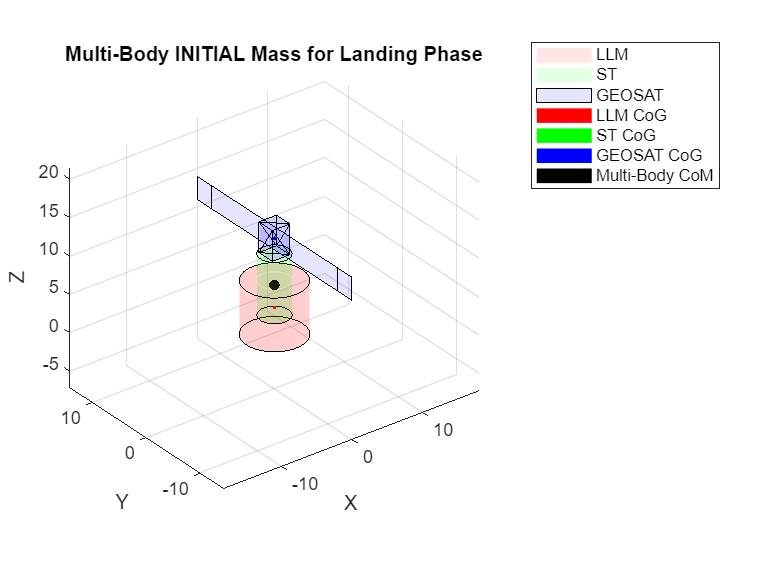

% 3D models
plot_stack(LLM.size.radius, LLM.size.height, ...
           ST.size.radius, ST.size.height, ...
           GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
           LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1000), ST.size.offset,'Multi-Body INITIAL Mass for Landing Phase')

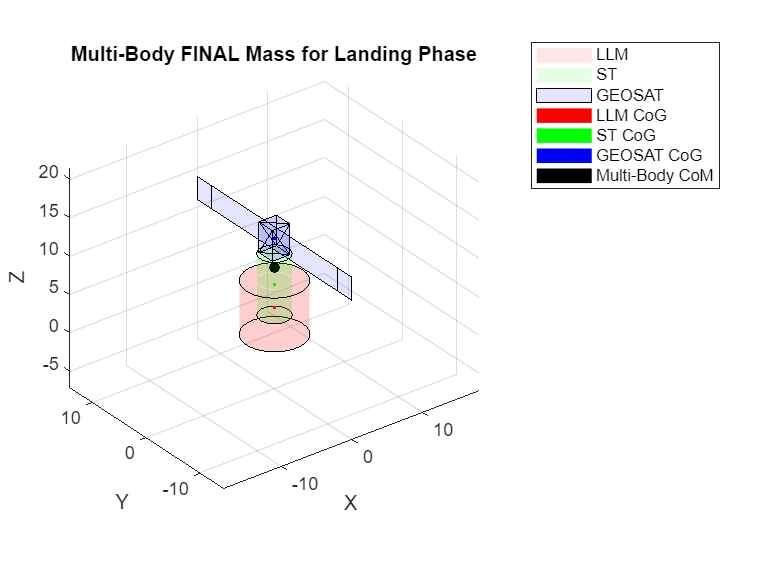

plot_stack(LLM.size.radius, LLM.size.height, ...
           ST.size.radius, ST.size.height, ...
           GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
           LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1), ST.size.offset,'Multi-Body FINAL Mass for Landing Phase')

## RCS Torque/Force Limit due to GEO target's CoM misalignment

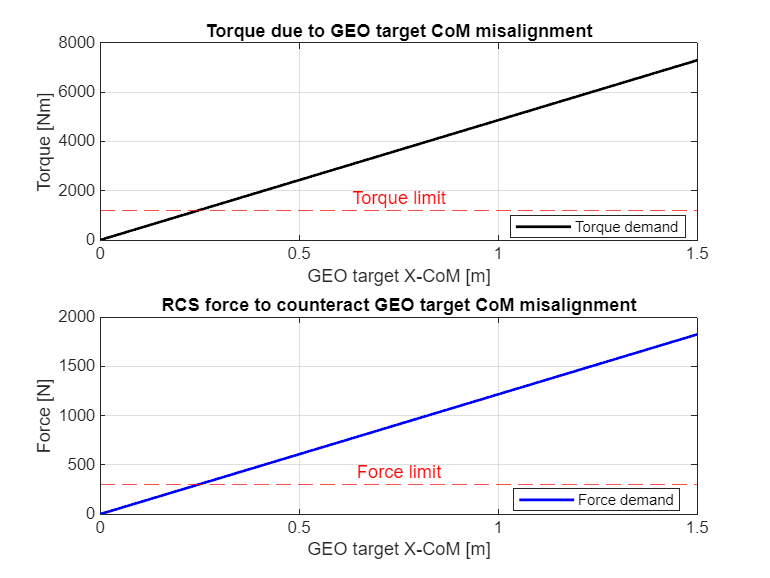

% Since ee are going to design the launch-landing module and the space tug,
% let's assume that their center of masses are going to be aligned.
% Evaluate torque to be applied by RCS in case the CoM of the GEO target
% has the CoM not aligned. Suppose it's shifted along X-axis

r = LLM.size.radius;
GEO_com = linspace(0,1.5,1000);

Torque_misallignment = GEOSAT.mass.dry * 1.622 * GEO_com;
F_rcs = Torque_misallignment / r;

% Max Torque and Force. TO BE UPDATED based on real RCS
limit_torque = 300;
limit_force = limit_torque / r;

limit_force = 300; % assuming 2 RCS activated in both directions, 500 N (more or less the force of the RCS thrusters of Altair Lander)
limit_torque = limit_force * r;

figure

% ---- Subplot 1: Torque ----
subplot(2,1,1)
plot(GEO_com, Torque_misallignment, 'k-', 'LineWidth', 1.5); hold on; grid on
yline( limit_torque, 'r--', 'Torque limit', 'LabelHorizontalAlignment','center');
title('Torque due to GEO target CoM misalignment')
xlabel('GEO target X-CoM [m]')
ylabel('Torque [Nm]')
legend('Torque demand','Location','best'); hold off

% ---- Subplot 2: Force ----
subplot(2,1,2)
plot(GEO_com, F_rcs, 'b-', 'LineWidth', 1.5); hold on; grid on
yline( limit_force, 'r--', 'Force limit', 'LabelHorizontalAlignment','center');
title('RCS force to counteract GEO target CoM misalignment')
xlabel('GEO target X-CoM [m]')
ylabel('Force [N]')
legend('Force demand','Location','best'); hold off

## Gimbal

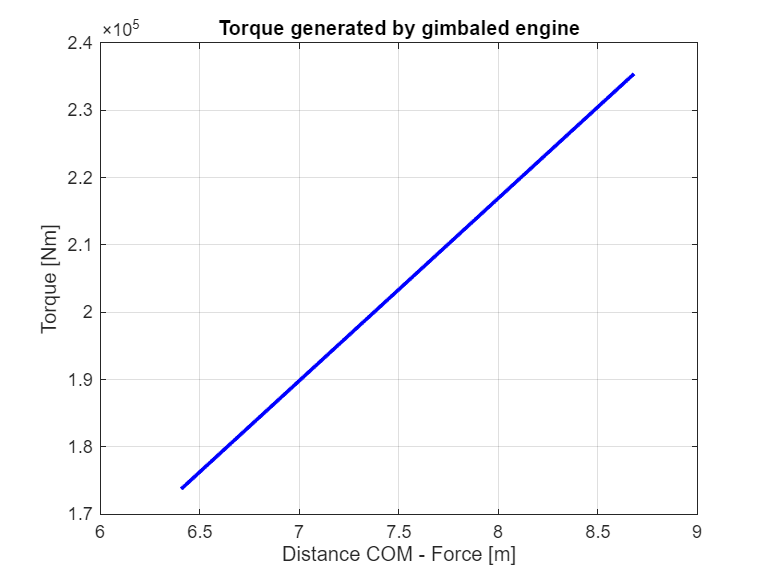

% Parameters
gimbal_angle = 7; % [deg]
Fmax = LLM.main_engine.Fmax; % Engine maximum thrust [N]

% Extract minimum and maximum values of the COM-force distance
d_F_com_min = COM_values(3,1000); 
d_F_com_max = COM_values(3,1);

% Create a range of values between min and max
d_F_com = linspace(d_F_com_min, d_F_com_max, 200);

% Compute lever arm and torque
lever = d_F_com .* sind(gimbal_angle);
T = Fmax .* lever;

% Plot
figure;
plot(d_F_com, T, 'b-', 'LineWidth', 2);
grid on;
xlabel('Distance COM - Force [m]');
ylabel('Torque [Nm]');
title('Torque generated by gimbaled engine');

## Simulation

% Parameters
g_moon = 1.62;  % m/s^2
g0 = 9.81;

f_plant = 100;
f_controller = 50;
f_guidance = 1;

switch_noise_pos = 0;
switch_noise_vel = 0;
switch_noise_ang = 0;
switch_noise_ome = 0;
sigma_pos = 0.5;
sigma_vel = 0.5;
sigma_att = 0.5;
sigma_ome = 0.5;

%Q = diag([0.5 0.5 0.5 0.5 0.5 0.5]);

%initial_state = [1 1 1 1 1 1 1 1 1];

vel0 = [0 0 0]';
pos0 = [0 0 0]';

% GUIDANCE LAW
% Initial state (start of PHASE 1 - Braking). Adjust to your case.
x0  = 289448.1899567346;        % initial downrange to target (m)
z0  = 15e3; 
y0  = 0e3; 
% initial altitude (m)
vx0 = -1695;          % horizontal speed toward target (m/s) (negative if x decreases)
vz0 = 0;  
vy0 = 0 ;               % vertical descending speed (m/s, negative downward)
r0 = [x0; y0; z0];
v0 = [vx0; vy0; vz0];

% Breaking phase
x1_t = 15000; y1_t = 0; z1_t = 8000;                                                                                                        
vx1_t = -202; vy1_t = 0; vz1_t = -30;
Tgo1  = max(10, (x1_t - x0) / (0.5*(vx0 + vx1_t)));
rt_breaking = [x1_t; y1_t; z1_t];
vt_breaking = [vx1_t; vy1_t; vz1_t];
tgo_breaking = Tgo1;

% Approach phase
x2_t = 0; z2_t = 100; y2_t = 0;
vx2_t = 0; vy2_t = 0; vz2_t = -8;
ax2_t = 0; ay2_t = 0; az2_t = 1.2*g_moon;
rt_approach = [x2_t; y2_t; z2_t];
vt_approach = [vx2_t; vy2_t; vz2_t];
at_approach = [ax2_t; ay2_t; az2_t];
tgo_approach = 150;

% Attitude 
% Initial values
c0 = (-2*(vt_breaking+2*v0))/tgo_breaking + 6*(rt_breaking - r0)/(tgo_breaking^2);
eul0 = force2eul(c0+[0;0;g_moon]);
q0 = eul2quat(eul0);
% Control Parameters
kr = 3*[0.5 0.5 0.8]';
ka = 0.2*kr;

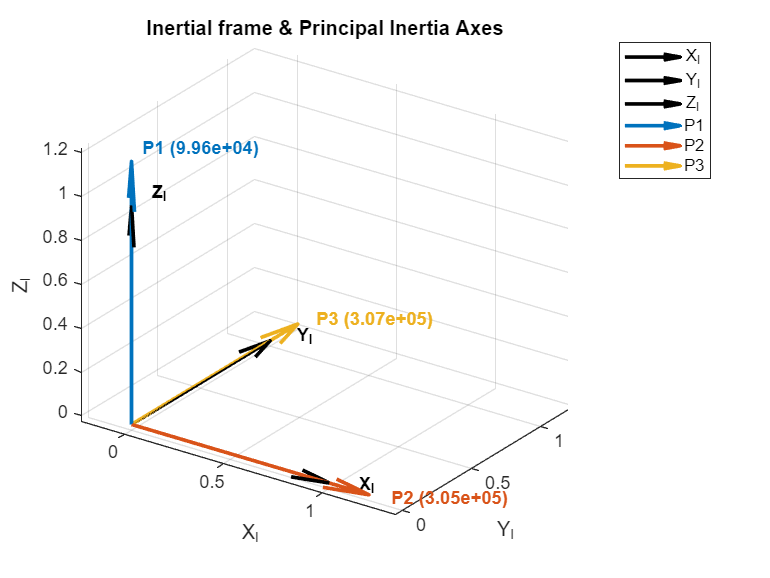

%% === Principal inertia axes: calcolo + plot (script eseguibile) ===


% --- INPUT: matrice di inerzia (simmetrica) ---
I = Inertia_MB(1:3,1:3,1);   % <-- Sostituisci con la tua I

% Se I è nel BODY e vuoi visualizzare rispetto all'INERZIALE:
use_body_I = false;        % true se I è espresso nel body frame
R_IB = eye(3);             % rotazione da body -> inerziale (colonne = assi body in coord. inerziali)
% Esempi: (scommenta una riga)
% R_IB = dcm_from_quat([0.9659 0 0.2588 0]);     % quaternione [w x y z]
% R_IB = dcm_from_euler321(deg2rad(20), deg2rad(10), deg2rad(-15)); % yaw,pitch,roll

% --- Calcolo assi principali ---
I = 0.5*(I+I.');                 % simmetrizzazione di sicurezza
[V,D] = eig(I);                  % colonne di V = autovettori
[lambda, ord] = sort(diag(D));   % ordina per I1<=I2<=I3
V = V(:,ord);
for k=1:3, V(:,k) = V(:,k)/norm(V(:,k)); end % normalizza
if det(V) < 0, V(:,1) = -V(:,1); end        % base destrorsa

% Trasforma nel frame inerziale se I era nel body
if use_body_I
    V_I = R_IB * V;
else
    V_I = V;
end


% --- Output numerico ---
%disp('Momenti principali (I1 <= I2 <= I3):');
%disp(lambda.');
%disp('Assi principali (colonne = P1, P2, P3) in coordinate INERZIALI:');
%disp(V_I);

% --- Plot 3D ---
figure('Color','w'); hold on; grid on; axis equal
xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');
title('Inertial frame & Principal Inertia Axes');

O = [0;0;0];
L_ref = 1.0;  L_pri = 1.2;

% Frame inerziale in nero
draw_axis(O, [1;0;0], L_ref, 'k', 'X_I');
draw_axis(O, [0;1;0], L_ref, 'k', 'Y_I');
draw_axis(O, [0;0;1], L_ref, 'k', 'Z_I');

% Assi principali (P1,P2,P3) con etichetta dei momenti
C = lines(3);
draw_axis(O, V_I(:,1), L_pri, C(1,:), sprintf('P1 (%.3g)', lambda(1)));
draw_axis(O, V_I(:,2), L_pri, C(2,:), sprintf('P2 (%.3g)', lambda(2)));
draw_axis(O, V_I(:,3), L_pri, C(3,:), sprintf('P3 (%.3g)', lambda(3)));

legend({'X_I','Y_I','Z_I','P1','P2','P3'}, 'Location','bestoutside');
view(35,25);


%% ====== Funzioni di supporto (nello stesso file va benissimo) ======
function draw_axis(o, dir, L, c, labeltxt)
    dir = dir / norm(dir);
    v = dir * L;
    quiver3(o(1), o(2), o(3), v(1), v(2), v(3), 0, ...
        'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', c);
    text(o(1)+1.05*v(1), o(2)+1.05*v(2), o(3)+1.05*v(3), ['  ' labeltxt], ...
        'FontWeight','bold', 'Color', c);
end

function R = dcm_from_quat(q) % q = [w x y z]
    q = q(:).'/norm(q);
    w=q(1); x=q(2); y=q(3); z=q(4);
    R = [1-2*(y^2+z^2),   2*(x*y - z*w), 2*(x*z + y*w);
         2*(x*y + z*w), 1-2*(x^2+z^2),   2*(y*z - x*w);
         2*(x*z - y*w),   2*(y*z + x*w), 1-2*(x^2+y^2)];
end

function R = dcm_from_euler321(yaw, pitch, roll) % Z-Y-X
    cy=cos(yaw);  sy=sin(yaw);
    cp=cos(pitch);sp=sin(pitch);
    cr=cos(roll); sr=sin(roll);
    Rz = [cy -sy 0; sy cy 0; 0 0 1];
    Ry = [cp 0 sp; 0 1 0; -sp 0 cp];
    Rx = [1 0 0; 0 cr -sr; 0 sr cr];
    R = Rz*Ry*Rx;
end

function R = in2body(f)  
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    f_rot = R1(bank)*f;
    pitch = atan2(f_rot(3,:),f_rot(1,:));
    R = R2(pitch)*R1(bank);
end


function eul = force2eul(f)
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    F_cmd_rot = R1(bank)*f;
    pitch = atan2(F_cmd_rot(3,:),F_cmd_rot(1,:));
    R = R2(pitch)*R1(bank);
    eul = rotm2eul(R,'ZYX');
    eulx = eul(3); eulz = eul(1);
    eul(1) = eulx; eul(3) = eulz;
    eul = wrapToPi(eul);
end

